## Dynamical analysis

We plan to extend the definition provided for kinematic analysis for data required by dynamical analysis (inertias and forces).

Next we will form equations of motion for the system of unconstrained bodies.

Finally we will solve the general multibody equations of motion.

### Bodies, inertias, and coordinates

mbs = init_mbs();
% mbs = add_body(mbs, "ground");
mbs = add_body(mbs, "crank", -0.1, 0.1, -deg2rad(30), 'm', 2.0, 'Ic', 2.0 * 0.2^2 / 12);
mbs = add_body(mbs, "link", -0.45, 0.1, deg2rad(15), 'm', 1.0, 'Ic', 0.5^2 / 12);
mbs = add_body(mbs, "slider", -0.6, 'm', 3.0, 'Ic', 0.1)

mbs = struct with fields:
     bodies: [1×3 struct]
     joints: [1×1 struct]
         nq: 9
         nc: 0
    gravity: []


Get mass matrix

M = mass_matrix(mbs)

M =     2.0000         0         0         0         0         0         0         0         0
         0    2.0000         0         0         0         0         0         0         0
         0         0    0.0067         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0    0.0208         0         0         0
         0         0         0         0         0         0    3.0000         0         0
         0         0         0         0         0         0         0    3.0000         0
         0         0         0         0         0         0         0         0    0.1000


### Forces definition

mbs = add_gravity(mbs, [0, -9.81]);

### Force vector

q0 = initial_position(mbs);
F = forces(mbs, q0)

F =          0
  -19.6200
         0
         0
   -9.8100
         0
         0
  -29.4300
         0


Simple checking for the gravity forces

qpp = M\F

qpp =          0
   -9.8100
         0
         0
   -9.8100
         0
         0
   -9.8100
         0


### Solve system using EulerCromer

Define all the inputs to the system

% [t, U, V] = EulerCromer(accfun, T, U_0, V_0, dt)
accfun = @(u, v, t)acceleration(mbs, u, v, t);
T = 1.0;
qd0 = zeros(size(q0)); % initial velocity
qd0([1, 5]) = -0.1; % Set vx of crank and vy of link
h = 0.01;
[t, Q, Qp] = EulerCromer(accfun, T, q0, qd0, h);


Make some plots to check the results

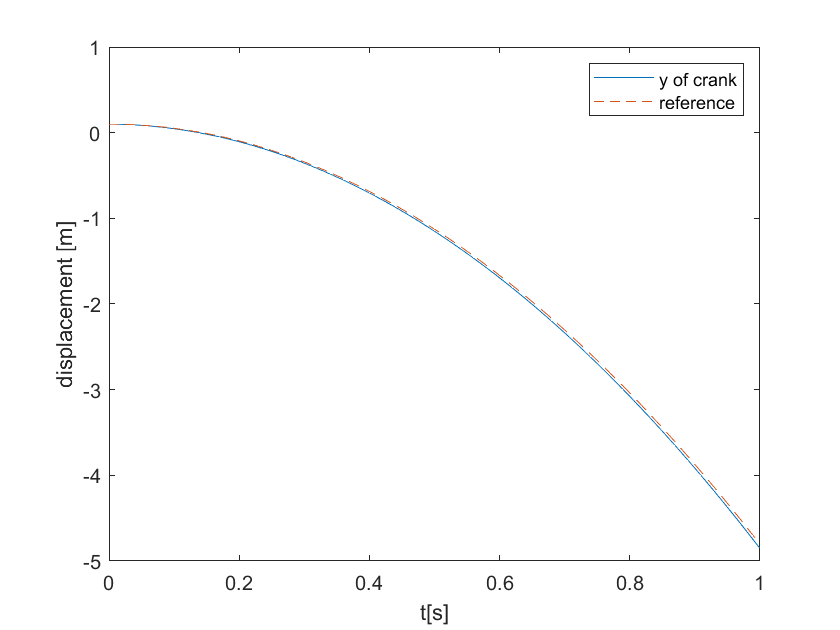

plot(t, Q(:, 2), t, q0(2) + t.*qd0(2) - 9.81 * 0.5 .* t .^ 2, '--')
legend('y of crank', 'reference')
xlabel('t[s]')
ylabel('displacement [m]')

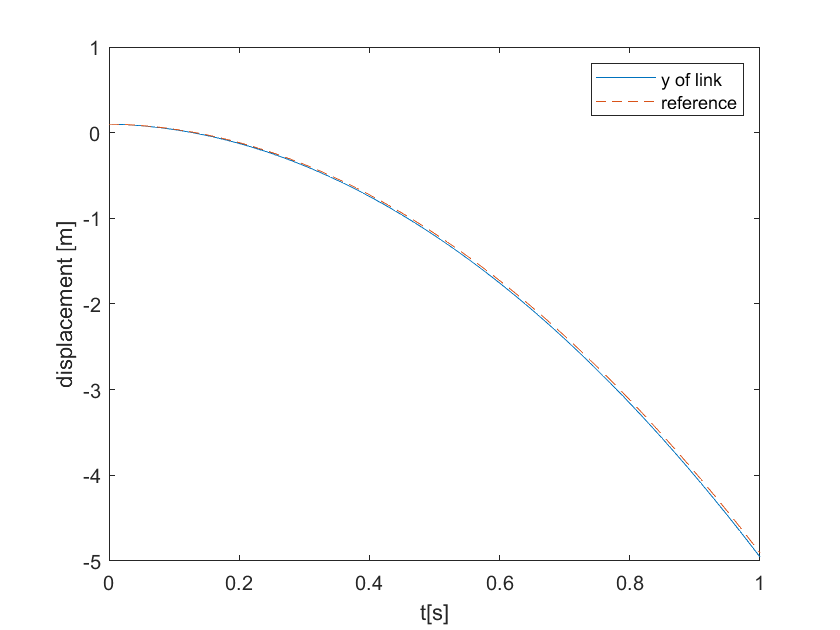

plot(t, Q(:, 5), t, q0(5) + t.*qd0(5) - 9.81 * 0.5 .* t .^ 2, '--')
legend('y of link', 'reference')
xlabel('t[s]')
ylabel('displacement [m]')

## System two - single body with simple constraint under gravity

mbs = init_mbs();
% mbs = add_body(mbs, "ground");
mbs = add_body(mbs, "block", 0.1, 0.1, -deg2rad(30), 'm', 2.0, 'Ic', 2.0 * 0.2^2 / 12);
mbs = add_simple_joint(mbs, "blockx", "block", "x", 0.1);


mbs = add_gravity(mbs, [7.12, 12.9]);

q0 = initial_position(mbs);
qd0 = zeros(size(q0));
accfun = @(u, v, t)acceleration(mbs, u, v, t);
T = 1.0;
h = 0.01;
[t, Q, Qp] = EulerCromer(accfun, T, q0, qd0, h);

Plot and check

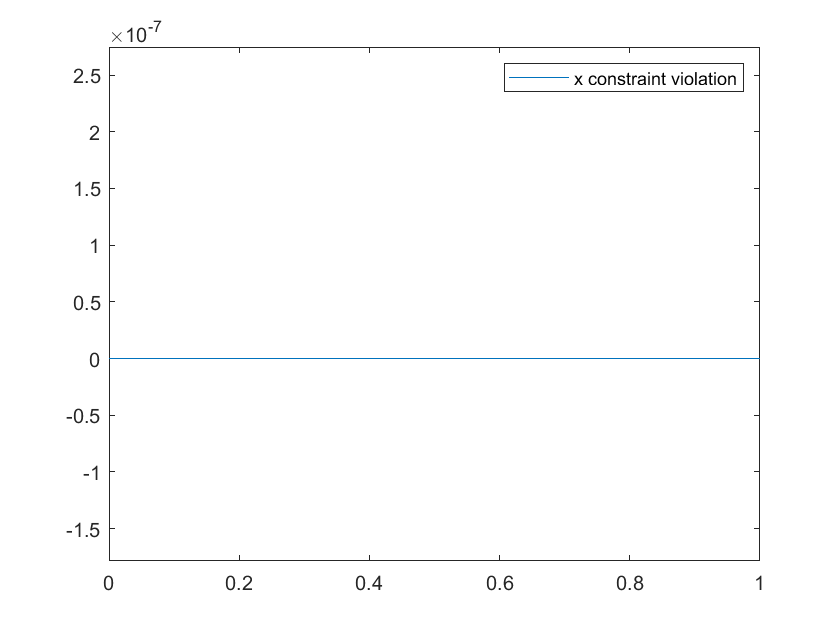

plot(t, Q(:, 1) - q0(1))
legend('x constraint violation')

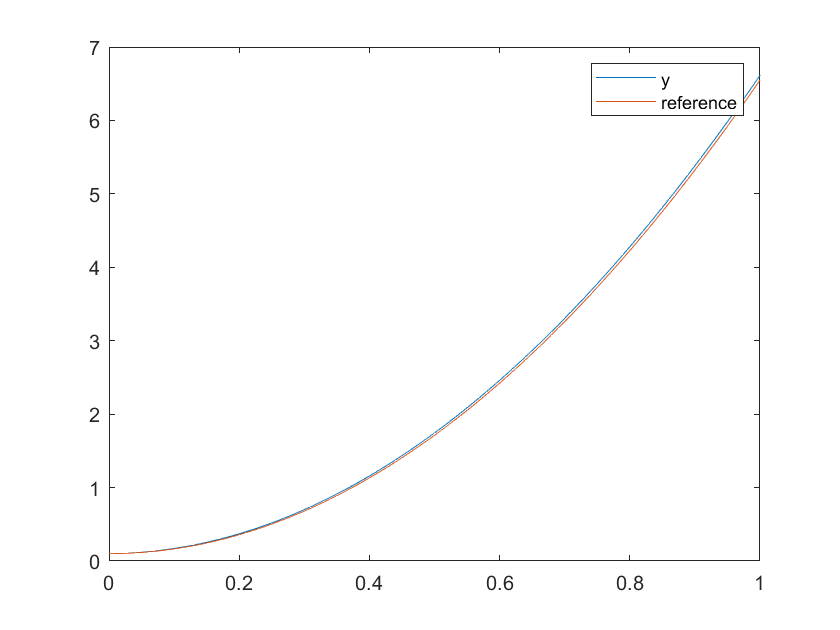

plot(t, Q(:, 2), t, q0(2) + 0.5 * 12.9 .* t.^2)
legend('y', 'reference')

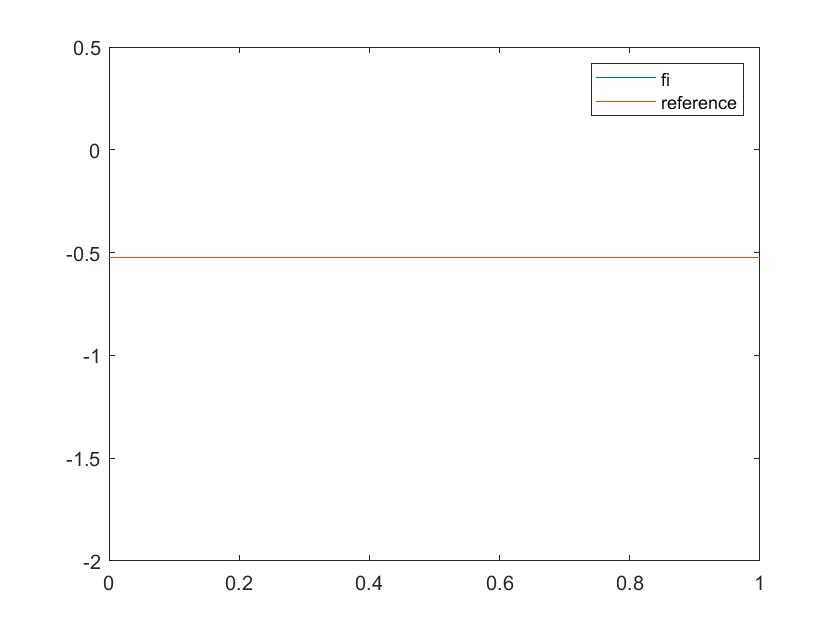

plot(t, Q(:, 3), t, q0(3) * ones(size(t)))
legend('fi', 'reference')

## Third example - pebble in parabolic motion

mbs = init_mbs();
% mbs = add_body(mbs, "ground");
mbs = add_body(mbs, "pebble", 0.0, 1.8, 0.0, 'm', 1.0, 'Ic', 0.05);
om0 = 1.2; % rad/s
omd = 0.1;
mbs = add_driving_joint(mbs, "pebblerotation", "pebble", ...
    "fi", @(t)om0 * t + 0.5 * omd * t ^ 2);

mbs = add_gravity(mbs, [0.0, -9.81]);

q0 = initial_position(mbs);
qd0 = [3, 2, om0];
accfun = @(u, v, t)acceleration(mbs, u, v, t);
T = 1.0;
h = 0.01;
[t, Q, Qp] = EulerCromer(accfun, T, q0, qd0, h);

Some checking plots

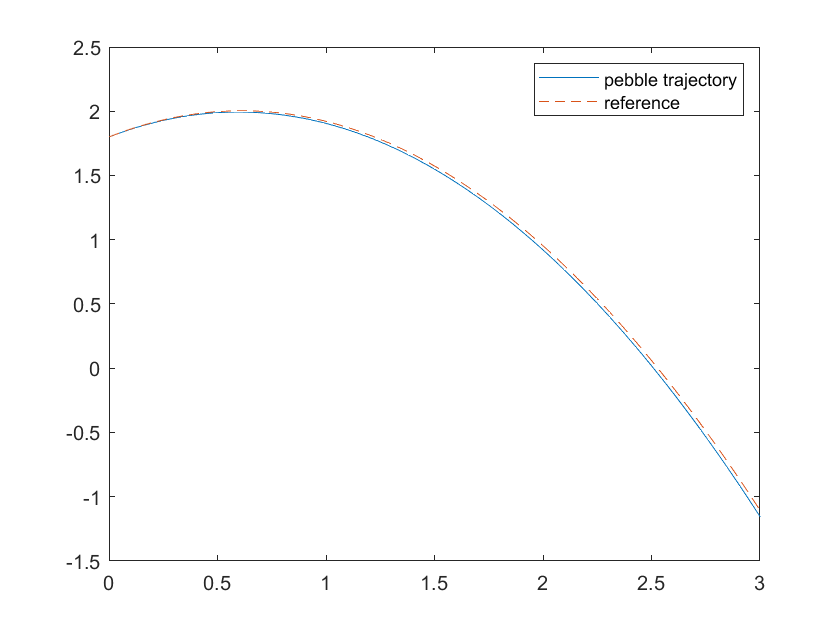

plot(Q(:, 1), Q(:, 2), ...
    q0(1) + qd0(1) .* t, q0(2) + qd0(2) .* t + 0.5 * (-9.81) .* t .^ 2, '--')
legend('pebble trajectory', 'reference')

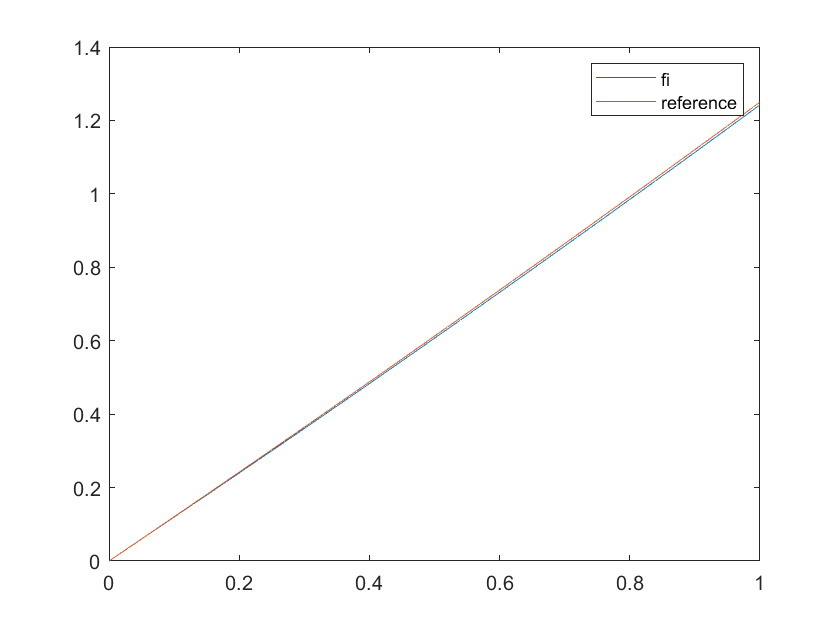


plot(t, Q(:, 3), t, om0 .* t + 0.5 * omd .* t .^ 2)
legend('fi', 'reference')

## 4th example - physical pendulum

Solve the pendulum as multibody system and compare results with differential equation 


$$I_0 \theta^¨ =-\textrm{mg}\frac{l}{2}\sin \theta$$


% Pendulum data
m = 2.0;
l = 1.0;
theta0 = deg2rad(120);
g = 9.81;
Io = m*l^2/3;
tf = 2.0;


Solution using 1 dof differential equations

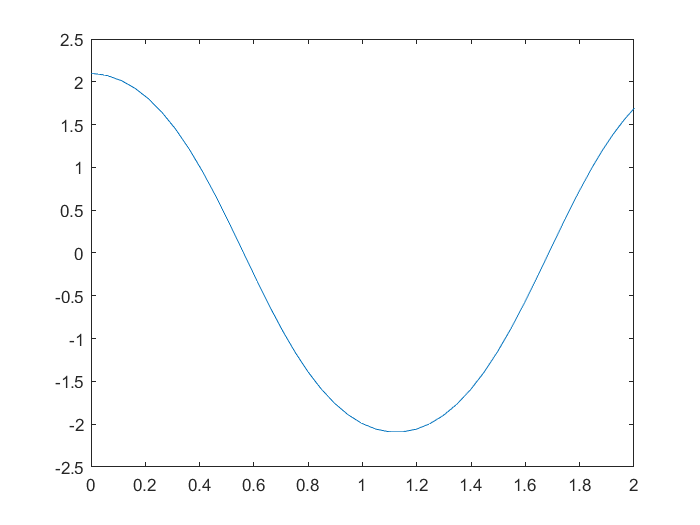

y0 = [theta0; 0.0]; % angle and its initial velocity

odefun = @(t, y) [y(2); -m * g * l / 2 * sin(y(1)) / Io];
tspan = [0.0, tf];
[t, y] = ode45(odefun, tspan, y0);

plot(t, y(:, 1))

Solution using MBD method

mbs = init_mbs();
mbs = add_body(mbs, "ground");
mbs = add_body(mbs, "pendulum", 0.5*l*cos(theta0), 0.5*l*sin(theta0), theta0, ...
    'm', m, 'Ic', m*l^2/12);

% Simple joints
mbs = add_simple_joint(mbs, "groundx", "ground", "x", 0);
mbs = add_simple_joint(mbs, "groundy", "ground", "y", 0);
mbs = add_simple_joint(mbs, "groundangle", "ground", "fi", 0);

mbs = add_revolute(mbs, "revO", "ground", [0; 0], "pendulum", [-0.5 * l, 0.0]);


mbs = add_gravity(mbs, [g, 0]);

q0 = initial_position(mbs);
qd0 = zeros(size(q0));
accfun = @(u, v, t)acceleration(mbs, u, v, t);
h = 0.002;
[t2, Q, Qp] = EulerCromer(accfun, tf, q0, qd0, h);

Compare results

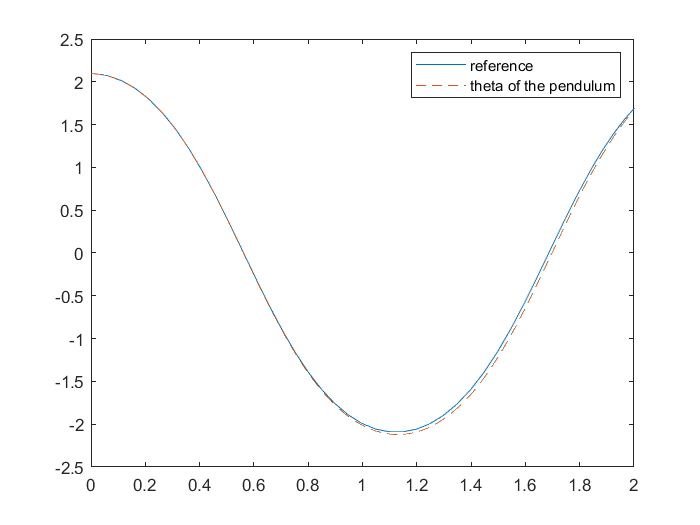

plot(t, y(:, 1), t2, Q(:, 6), '--')
legend('reference', 'theta of the pendulum')

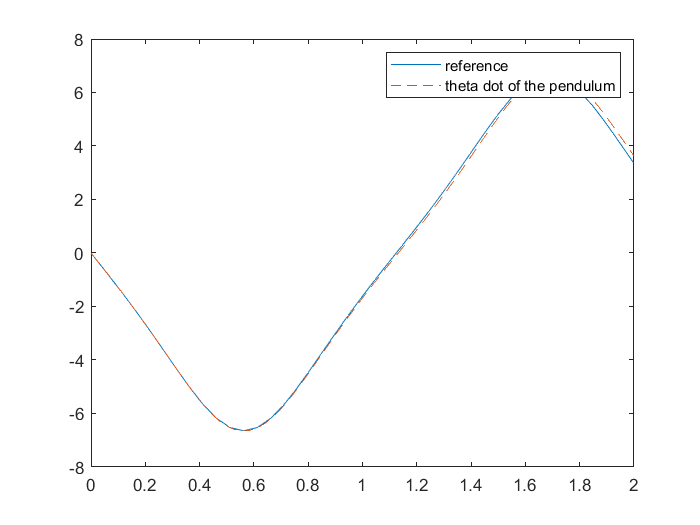


plot(t, y(:, 2), t2, Qp(:, 6), '--')
legend('reference', 'theta dot of the pendulum')

Simple animation - prepare the plot and change internal plot data in the loop

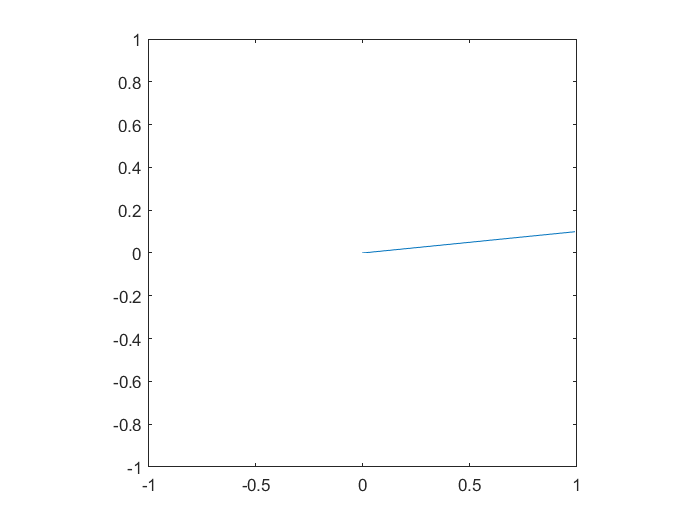

hpl = plot([0.0, l * sin(Q(1, 6))], -[0.0, l*cos(Q(1, 6))]);
axis equal
xlim([-l, l])
ylim([-l, l])
for ii = 1:length(t2)
    hpl.XData(2) = l * sin(Q(ii, 6));
    hpl.YData(2) = -l * cos(Q(ii, 6));    
    drawnow();
    pause(h);
end